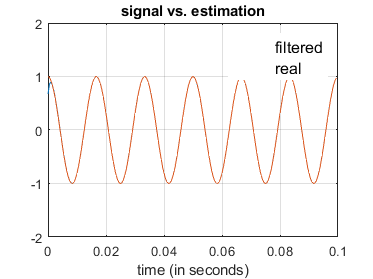

clc;
clear;
% matlab colors and preset
NMatlabRed      = [0.8500   0.3250   0.0980];
NMatlabYellow   = [0.929    0.694    0.125 ];
NMatlabBlue     = [0        0.4470   0.7410];  
NMatlabViolet   = [0.4940   0.1840   0.5560];
NMatlabGreen    = [0.4660   0.6740   0.1880];
NMatlabCyan     = [0.3010   0.7450   0.9330];
NMatlabBordeaux = [0.6350   0.0780   0.1840]; 

% ========= Table Paper ===============%
Fc = 60; %frequency 60Hz
Av =1;  % amplitude
Ts = 0.0005; % 1/0.0005 = 2 kHz  campionamento
StopTime = 0.1;             % seconds
t = (0:Ts:StopTime-Ts)';     % seconds
x1 = Av*cos(0);
x2 = Av*sin(0);
v = x1*cos(2*pi*Fc*t) - x2*sin(2*pi*Fc*t);

Q = eye(2);
R = 1;

Tf    = 0.1;                               % simulation time  
[filtered] = kalmanfilter(v, Q, R, Tf);

figure;
plot(t, filtered, t, v);
ylim([-2 2]);
xlabel('time (in seconds)');
legA = legend('filtered','real');
set(legA,'FontSize',12)
title('signal vs. estimation');
grid on

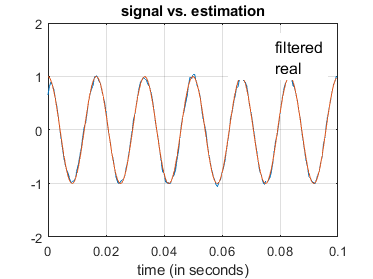


% %add a noise
% SNRdb = 10; %Given SNRdb
% variance = 1/(Ts*(10^(SNRdb/10))); 
% W = sqrt(variance).*randn(1,size(x1,2)); %Gaussian white noise W
% x1 = x1 + W; %Add the noise

%oppure
std=0.05;              % standard deviation of 5%
meanValue=0;           % mean=0
Noise_signal = v + std*randn(size(v)) + meanValue;
[filtered_noise] = kalmanfilter(Noise_signal, Q, R, Tf);

figure;
plot(t, filtered_noise, t, v);
ylim([-2 2]);
xlabel('time (in seconds)');
legA = legend('filtered','real');
set(legA,'FontSize',12)
title('signal vs. estimation');
grid on

function [filtered_sig]= kalmanfilter(signal,Q_in,R_in,simulation_time)
%this Kalman filter has been modified to follow an input siusoidal
%"signal" with approximatley 60 Hz.
%Q_in and R_in are tuning parameters.
%simulation_time is the total simulation time(match input-signal).
%filtered_sig is the Kalman-filtered output of the signal.

time_vec=linspace(0,simulation_time,length(signal));
A=[1.00 0.0;0.0 1.00];
w=2*pi*60;

%initilize values
x0=[0;0];
p0=1*eye(2);
Q=Q_in;
R=R_in;

z1 = zeros(size(signal));
z2 = zeros(size(signal));

filtered_sig = zeros(size(signal));

for i=1:max(size(signal))
xn_nm1=x0;
c=[cos(w*time_vec(i)) -sin(w*time_vec(i))];
%1 prediction error covariance 
pn_nm1=A*p0*A'+Q;
%2 kalman gain equation
kn=A*pn_nm1*c'*inv(c*pn_nm1*c'+R);
%3 filter equation
xnn=xn_nm1+kn*(signal(i)-c*xn_nm1);
%4 error covariance
pnn=pn_nm1-kn*c*pn_nm1;
z1(i)=xnn(1);
z2(i)=xnn(2);
%recreating the sinusoid
filtered_sig(i)=c*[z1(i);z2(i)];
x0=xnn;
p0=pnn;
end
end